## Pablo Vega Gallego, VC, FIB.

# Sessió 4

En aquesta sessió tractarem de trobar a Odlaw, que ens diuen que porta una samarreta amb unes linies grogues i negres.

Comencem per llegir la imatge i mirar el que tenim.

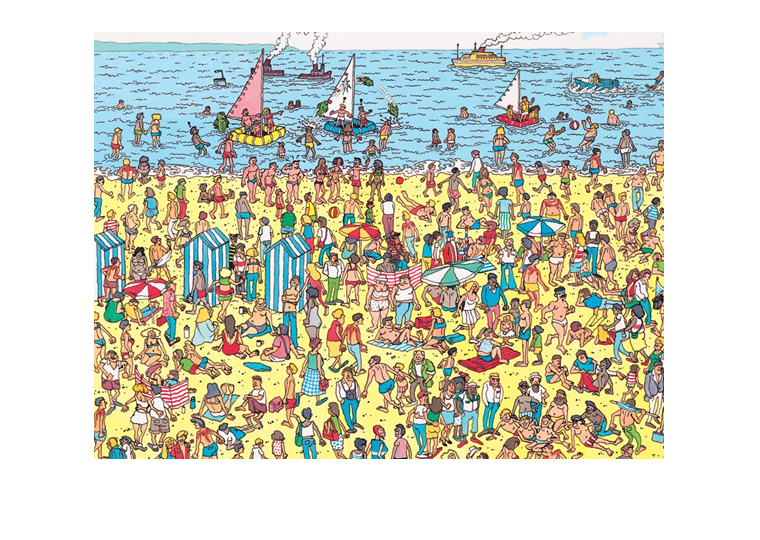

I = imread('Wally.png');
original = I;
imshow(I);

Apliquem un filtre de mediana a cada capa de color per individual per tal d'eliminar el soroll de la imatge. Com podeu veurem, tenim una imatge 'suavitzada'.

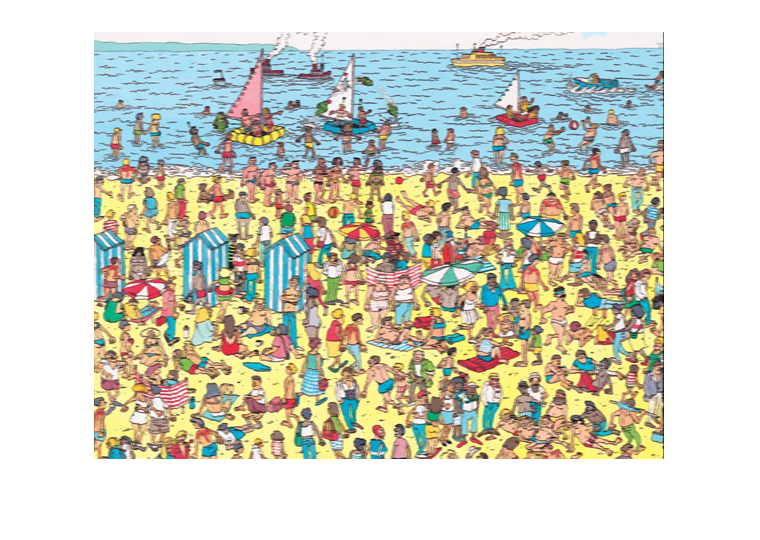

I(:, :, 1) = medfilt2(I(:, :, 1), [1 4]);
I(:, :, 2) = medfilt2(I(:, :, 2), [1 4]);
I(:, :, 3) = medfilt2(I(:, :, 3), [1 4]);
imshow(I);

Transformarem l'espai RGB de la imatge en un HSV per tal de trobar els colors grocs i negres de la imatge d'una manera més fàcil i còmode.

HSV -> Hue(graus dels colors) Saturation(-saturació +blanc) Value(-value +negre)

El color groc en HSV correspon a uns 50º aproximadament, tenint en compte les diferents tonalitats de groc, farem una petita tolerància cap a l'esquerra i cap a la dreta. Aquesta informació ho trobarem a la 1a dimensió de la matriu que correspon amb 'Hue'. Les dades de la matriu estàn compreses entre valors [0, 1].

El color negre no ens importa les graus, simplement ens importa el 'Value' que es la 3a dimensió de la matriu que retorna la funció rgb2hsv, i els valors petits d'aquesta matriu correspon amb els colors negres de la imatge. 

Comencem per realitzar la transformació:

HSVI = rgb2hsv(I);

Ara començarem a realitzar el filtratge per colors. Començarem per el groc que ens han dit que era 50º.

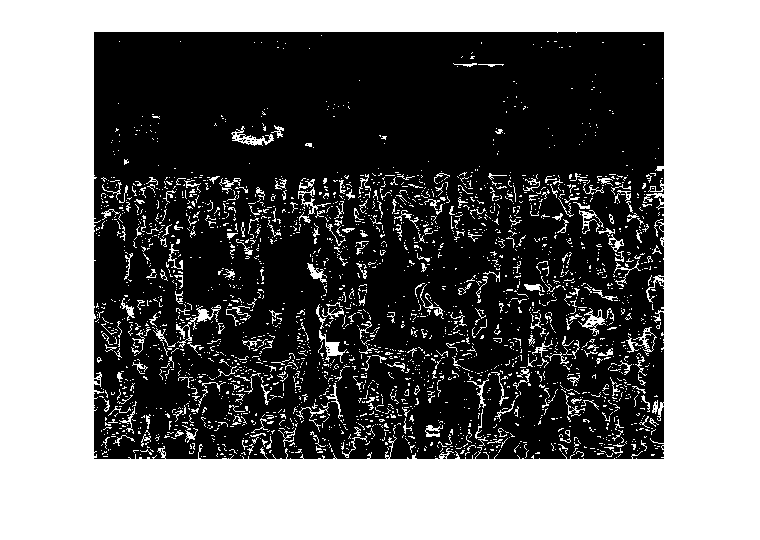

tolerancia = 5;
GROC = (((50-tolerancia)/360) <= HSVI(:, :, 1)) & (((50 + tolerancia)/360) >= HSVI(:, :, 1));
imshow(GROC)

I ara amb el negre:

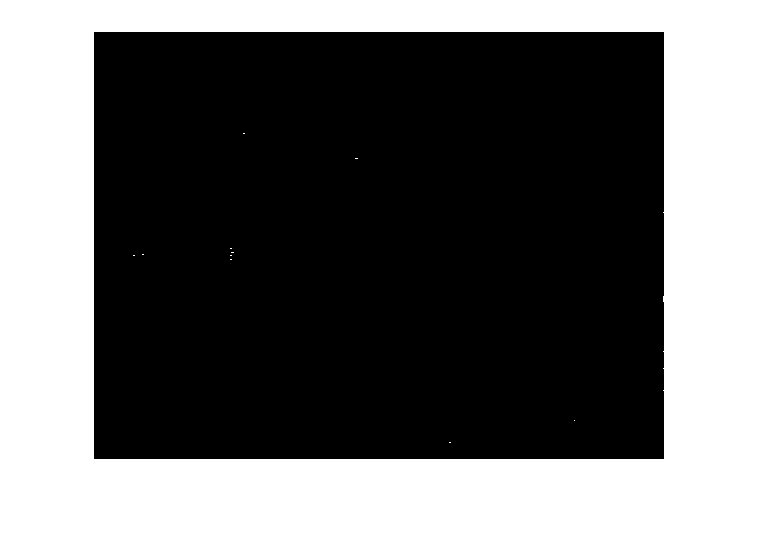

NEGRE = HSVI(:, :, 3) < 0.1;
imshow(NEGRE)

En les dues imatges podem veure els objectes grocs i negre. Si ens fixem bé, a la imatge de només colors negres podem començar a visualitzar les ratlles de la samarreta del personatge que estem buscant.

Hem de crear dos elements estructurals: un per detectar linies llunyanes SE7 i un per les properes.

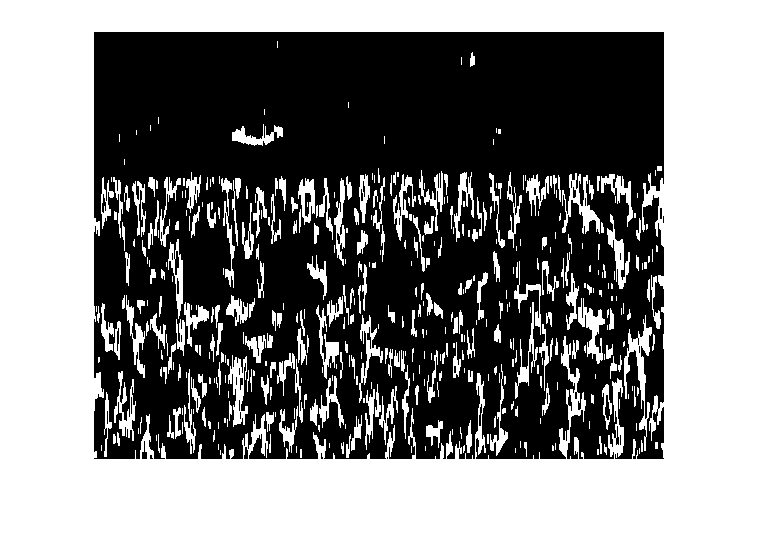

SE7 = strel('line',7,90);
SE = strel('line',5,90);
GROC = imclose(GROC, SE7);
GROC = imopen(GROC, SE);
imshow(GROC)

Repetim el mateix amb els negres.

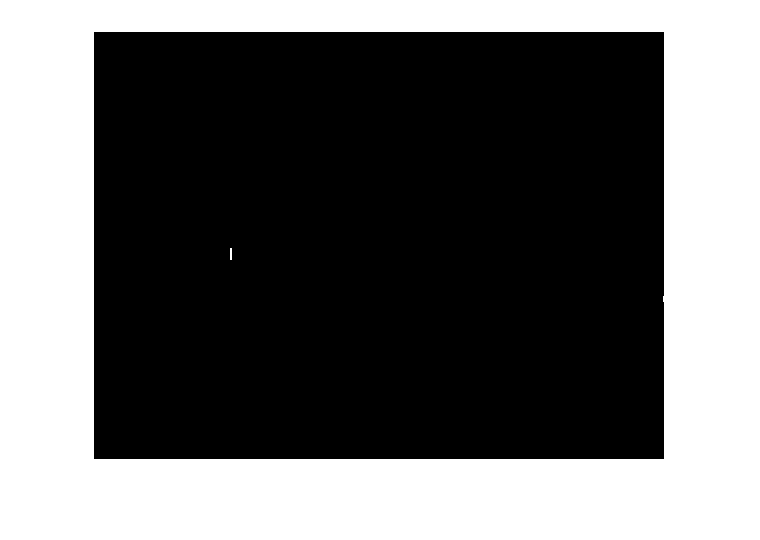

NEGRE = imclose(NEGRE, SE7);
NEGRE = imopen(NEGRE, SE);
imshow(NEGRE)

Fem l'AND l'ogica per veure les zones on encaixen el que busquem.

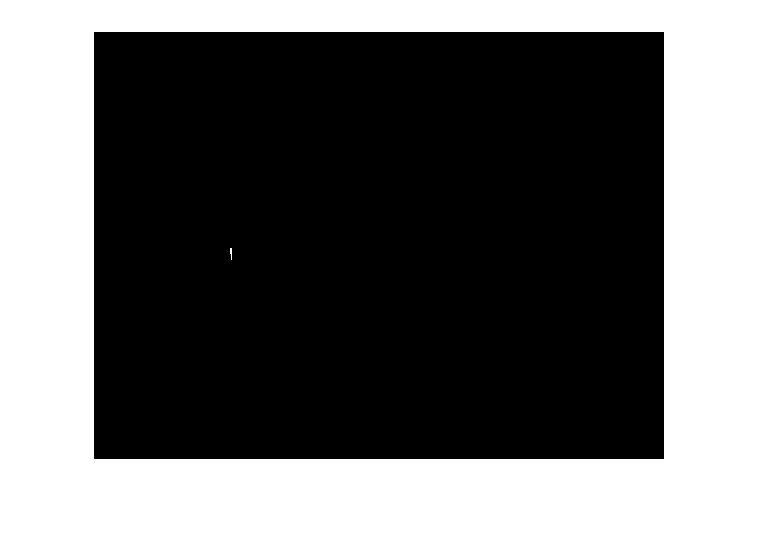

RES = GROC&NEGRE;
imshow(RES)

Dilatem la imatge amb un quadrat més gran i després amb un més petit. Fem la resta del resultat i creem un marc per tal d'encapsular el resultat.

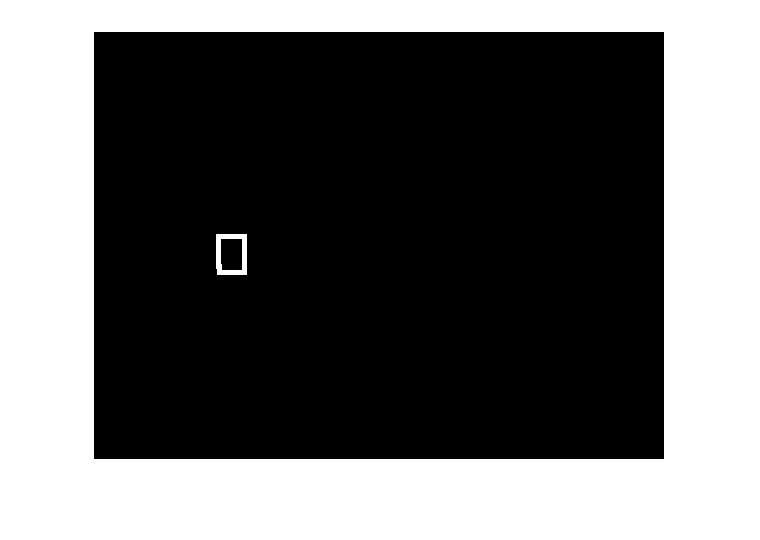

SE1 = strel('square', 30);
SE2 = strel('square', 20);
RES1 = imdilate(RES, SE1);
RES2 = imdilate(RES, SE2);
RES = RES2 - RES1;
imshow(RES1 - RES2)

Fem l'overlapping de la imatge original/grissos amb el quadrat per veure on és Odlaw.

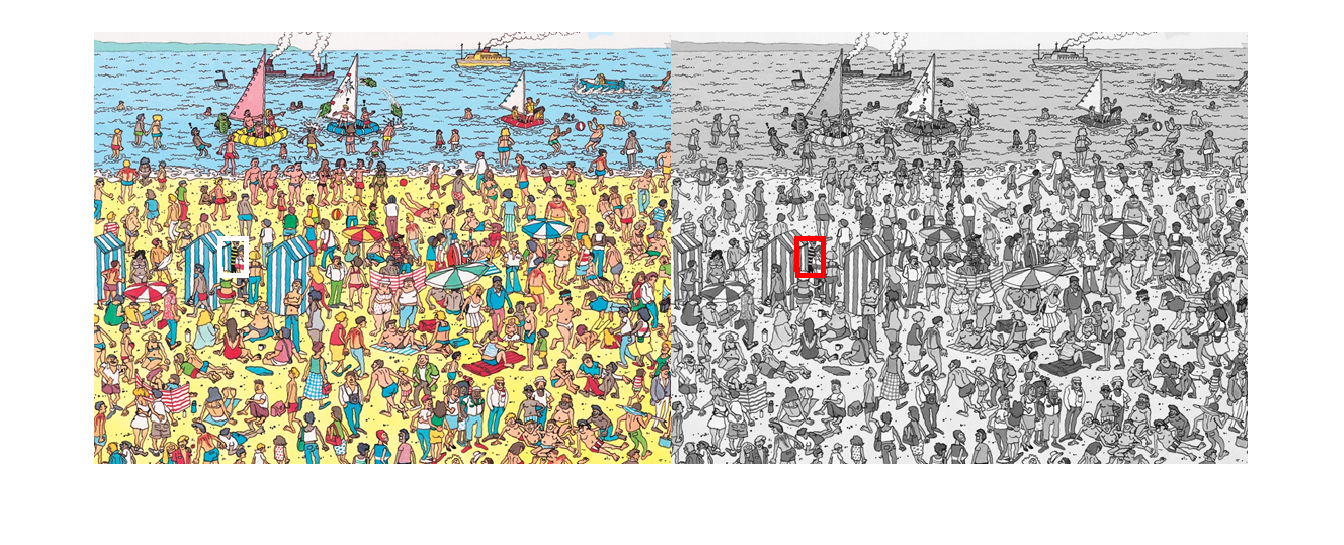

final = imoverlay(original, RES, 'white');
grises = rgb2gray(original);
final2 = imoverlay(grises, RES, 'red');
montage({final, final2});